
supressed_print= evalc('run Term_Project_Live_Script.mlx');

clear supressed_print

sympref('FloatingPoint',true);

addpath('Clay Testing Format')

## Part Two - Performance Criteria, Improved Lyapunov Stability Arguments, and Nonlinear Variable Structure Controller 

### Performance Criteria

A nonlinear control scheme is desired that can take the state from $\overset{\rightharpoonup}{x_0} ~=~(110^^\circ,0)$ to the upward operating point within five seconds. It is desired to have a final velocity of zero and a steady state angular error of less than half a degree. It is also desired to eliminate chatter in the actuator at steady state - only controllers with zero steady state chatter can be considered successful. Finally, the controller must be robust to model and parameter inaccuracies.

### Expanded Lyapunov Stability 

The stability analysis in part one utilized Lyapunov's indirect method which had severe limitations. It is desired to utilize a Lyapunov-stability-based control technique that holds for a much larger region of the state space. A control law that is guaranteed to make the desired equilibrium point attractive globally is the ideal scenario. It is shown that this ideal scenario is not achievable with the proposed control law given that the system is effort limited (15 V rails). Additionally, the 100Hz measurement sample rate for the system is not considered in the stability analysis. Rather, it will be compensated for with an additional control structure; a boundary layer that takes over near the switching surface. 

#### Defining Lyapunov Function $V(s)$ and Switching Surface $s(\overset{\rightharpoonup}{x}) ~=~0$ 

A Lyapunov function $V(s)$ is defined in terms of scalar $s(\overset{\rightharpoonup}{x})$ such that it is positive definite. The scalar is defined:


$$s(\overset{\rightharpoonup}{x}) ~=~ \dot{\theta} + \lambda\theta$$


syms lambda v_hat v_o v_s s s_dot eta K


s_eqn = s == theta_dot + lambda*theta; 

The equation $s(\overset{\rightharpoonup}{x}) ~=~0$ describes a surface in the state space. On this surface, a decaying linear polynomial in phase variables is realized. If scalar $V(s)$ is defined as:


$$V(s) ~=~ \frac{s^2}{2}$$


then $V(s)$ is positive definite. When $V(s)$ is minimized, the system is on the switching surface and the states will decay to zero asymptotically. On the switching surface


$$ \dot{\theta} + \lambda\theta ~=~ 0$$


and


$$\theta(t + t_{tp}) ~=~ e^{-{\lambda}(t-t_{tp})}\theta(t_{tp})$$


where $t_{tp}$ is the transport time; the time when the system reached the switching surface, and $t$ is the current time. 

#### Negative Definiteness of $\dot{V}(s)$

To prove asymptotic stability, $\dot{V}(s)$ must be negative definite. This is where the control law enters consideration. A control actuation will be selected such that, through state feedback, $\dot{V}(s)$ can be made negative definite. It is shown here that there are practical limitations to this; but an effective control law can still be designed for the real input limited system. 


$$\dot{V}(s)  ~=~ s\dot{s}(s)$$


where $\dot{s}(s)$ denotes the derivative of $s(\overset{\rightharpoonup}{x}) $ formulated explicitly in terms of $s$. The derivative cannot be formulated in this manner immediately, so for now:


$$\dot{s}(\overset{\rightharpoonup}{x}, v_m) = \ddot{\theta}(\overset{\rightharpoonup}{x}, v_m)  + \lambda\dot\theta$$
 

s_dot_eqn = s_dot == theta_ddot + lambda*theta_dot;
s_dot_eqn = subs(s_dot_eqn, theta_ddot, rhs(isolate(ModPendulumEOM , theta_ddot)));

Using terms from $\ddot{\theta}$, $\dot{s}(\overset{\rightharpoonup}{x}, v_m)$ can be rewritten. 


$$\ddot{\theta}(\overset{\rightharpoonup}{x}, v_m) 

~ =~
\frac{L\,M\,g\,\sin \left(\theta \right)-T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)-\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }

~+~ \frac{K_c \,v_m }{R_a(J_m \,N+J_p) }}

~=~

f(\overset{\rightharpoonup}{x})+ bv_m$$


theta_ddot_eqn = NL_PendulumSS(2);

where 

b = B(2);
b_n = double(subs(subs(b, [L, M, g, J_m, J_p, N, K_m, T_ba]...
    ,[L_n, M_n, g_n, Jm, Jp, N_n, Km, T_ba_n]), K_c/R_a, KcRa));
f = rhs(theta_ddot_eqn - b*v_m);


$$f(\overset{\rightharpoonup}{x}) = \frac{L\,M\,g\,\sin \left(\theta \right)-T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)-\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }$$


and 


$$b ~=~ \frac{K_c  }{R_a(J_m \,N+J_p) }}$$


hence


$$\dot{s}(\overset{\rightharpoonup}{x}, v_m)  ~=~ f(\overset{\rightharpoonup}{x})+ bv_m + \lambda\dot{\theta}$$


It is desired to eliminate explicit dependance on the state of the nonlinear system from the Lyapunov function's derivative. If $\dot{V}(s)$, which is more generally a function of the state (i.e. $\dot{V}(\overset{\rightharpoonup}{x})$), can be kept in terms of $s$ alone, then the negative definiteness can be a reasoned in a straightforward manner. To achieve this, the nonlinearities of the plant are cancelled out, and $\dot{s}$ is driven to zero, via a nullifying actuation voltage $\hat{v}$. 


$$\hat{\dot{s}} ~=~ \hat{f}(\overset{\rightharpoonup}{x})+ b\hat{v} + \lambda\dot{\theta}~=~0$$



$$

\hat{v} ~=~ -\frac{1}{b}(\hat{f}(\overset{\rightharpoonup}{x})+\lambda\dot{\theta})$$


where $\hat{f}(\overset{\rightharpoonup}{x})$ is the best estimate available of $f(\overset{\rightharpoonup}{x})$. Pluggin in the system dynamics

% Use symbolic toolbox to determine nullifying actuation v_hat
v_hat_eqn(theta_dot,theta)  = v_hat == rhs(isolate(rhs(s_dot_eqn) == 0, v_m));
simplify(subs(ModPendulumEOM, v_m, rhs(v_hat_eqn))); %Use to check that algebra was correct


$$\hat{v} =

-\frac{R_a{\left(J_m \,N+J_p \right)}}{K_c } 

\,{\left( \frac{L\,M\,g\,\sin \left(\theta \right)-T_{\textrm{ba}} \,\mathrm{sign}\left(\dot{\theta} \right)-\frac{K_c \,N\,\dot{\theta} }{K_m \,R_a }}{J_m \,N+J_p }

~+ ~

\lambda \,\dot{\theta}\right)}\,$$


or, numerically

%substitute in numerical parameters to v_hat
v_hat_eqn_num(theta_dot,theta, lambda) = subs(v_hat_eqn, [L, M, g, J_m, J_p, N, K_m, T_ba]...
    ,[L_n, M_n, g_n, Jm, Jp, N_n, Km, T_ba_n]);
v_hat_eqn_num(theta_dot,theta, lambda) = subs(v_hat_eqn_num, K_c/R_a,  KcRa);



$$\hat{v} =0.3501\,\dot{\theta} +1.0684\,\mathrm{sign}\left(\dot{\theta} \right)-0.6600\,\sin \left(\theta \right)-0.1144\,\lambda \,\dot{\theta}$$


An additional actuation $v_s$, formulated as a feedback law on $s$,  is added to $\hat{v}$ to give the total control actuation $v_m$.


$$v_m ~=~ \hat{v} + v_s(s)$$


Using this input, $\dot{s}$ is 


$$\dot{s}(\overset{\rightharpoonup}{x}, \hat{v}, s)  ~=~ f(\overset{\rightharpoonup}{x})+ b(\hat{v} + v_s(s)) + \lambda\dot{\theta}$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


f(\overset{\rightharpoonup}{x})

-

\hat{f}(\overset{\rightharpoonup}{x})-\lambda\dot{\theta}

+ 


 b v_s(s)+ \lambda\dot{\theta}$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


F(\overset{\rightharpoonup}{x})

+ 

 b v_s(s)$$


**First Practical Limitation on Negative Definiteness - Model Uncertainty**

Above, $F$ represents a mismatch between the model and the real system. This is not a completely satisfactory result because $\dot{s}$ is not a function of $s$ alone. Therefore, the model uncertainty is the first limitation on a proof of negative definiteness that encorporates a feedback law on $s$. 


$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})

+ 

 b v_s) ~<~ 0  $$
 

i.e. 


$$sbv_s ~<~ -sF(\overset{\rightharpoonup}{x})$$


If $v_s$ is not made large enough in magnitude, this inequality will surely fail. 

**Second Practical Limitation on Negative Definiteness - Saturated Actuation**

The second limitation comes from the voltage rails. The bounds on the actuation are  $\pm 15V$, 


$$|v_m| ~=~ |\hat{v} + v_s| \leq 15[V]$$
 

A trajectory requiring too much nullifying voltage at any point in time will saturate the actuator and $v_s$ will have additional requirements to satisfy negative definiteness. When this happens, $\hat{\dot{s}}  \neq 0$ and 


$$

\hat{v} ~=~ -\frac{1}{b}(\hat{f}(\overset{\rightharpoonup}{x})+\lambda\dot{\theta}) + \frac{1}{b} \hat{\dot{s}}$$



$$\dot{s}(\overset{\rightharpoonup}{x}, s)  ~=~ 


F(\overset{\rightharpoonup}{x})



+ \hat{\dot{s}}

+ 


 b v_s(s)

$$



$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})



+ \hat{\dot{s}}

+ 


 b v_s(s)) ~<~ 0  $$
 

Where now the condition for negative definiteness is affected by the value of $\hat{\dot{s}}$. This report will not address the possibility of reducing the model uncertainty, but $\lambda$ and a switching gain $K$will be tuned manually to ensure that, for our scenario, $\hat{\dot{s}}$ is zero and $\hat{v}$ stays far enough away from $\pm 15V$. 

### Nonlinear Variable Structure Controller Design

A control law with three meta-structures is proposed. The first is a switching law for $v_s$ that keeps $s ~=~0$ attractive in the presence of model uncertainty. 


$$v_s = -\frac{K}{b}sign(s)$$


%Use symbolic toolbox to check that the switching law algebra works out
v_s_eqn = v_s == K/b*sign(lhs(s_eqn));
v_os_eqn = v_o == rhs(v_hat_eqn) - rhs(v_s_eqn);
VSC_eqn = isolate(simplify(expand(subs(ModPendulumEOM, v_m, rhs(v_os_eqn)))), theta_ddot + lambda*theta_dot);
s_dot_check = subs(VSC_eqn, theta_ddot + lambda*theta_dot, s_dot);

The second is a smoothing proportional controller on $s$ that is implemented near a boundary layer. The discrete measurements available for feedback are shown to produce chatter in the actuator and an undesirable amount of swinging about the equilibrium point. If the aggressiveness is slowed down near the switching surface, this chatter is reduced or eliminated. 


$$v_s = -C_{BL}\frac{K}{b}s$$


The combination of the first two meta-structures is implemented as a saturation control law with suitably chosen pre and post-multiplying gains. The pre-multiplying gain $C_{BL}$ will control the size of the boundary layer along with the aggressiveness of the linear control law on $s$. The post multiplying gain $\frac{K}{b}$ will control the magnitude of the switching law outside the boundary layer. 

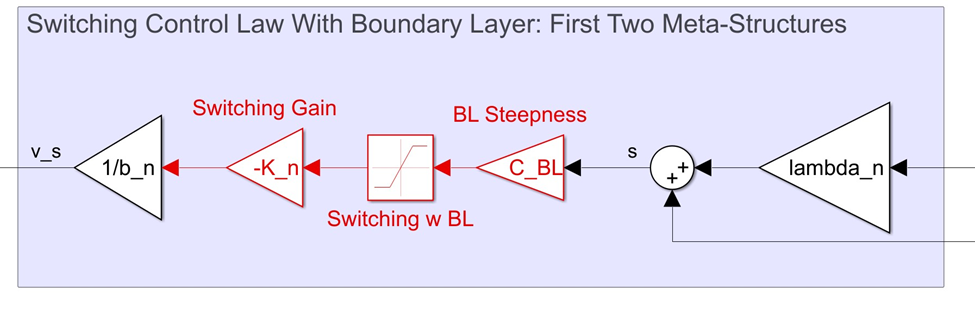

The third meta structure is a complete zeroing of the actuation if $|\theta|$ becomes suitably small. When this occurs, the static friction present in the system will take over, the actuation effort will cease, and an acceptable amount of steady state error will likely be present. Any steady state error present in the first two structures will result in actuation that only dissipates energy. If the control law evaluates to a constant voltage output at steady state and the system has reached an equilibrium with the static friction, the control effort is being dissipated as heat by the armature resistance. Additionally, if the boundary layer fails to prevent chatter, this law has a chance of preventing that. 

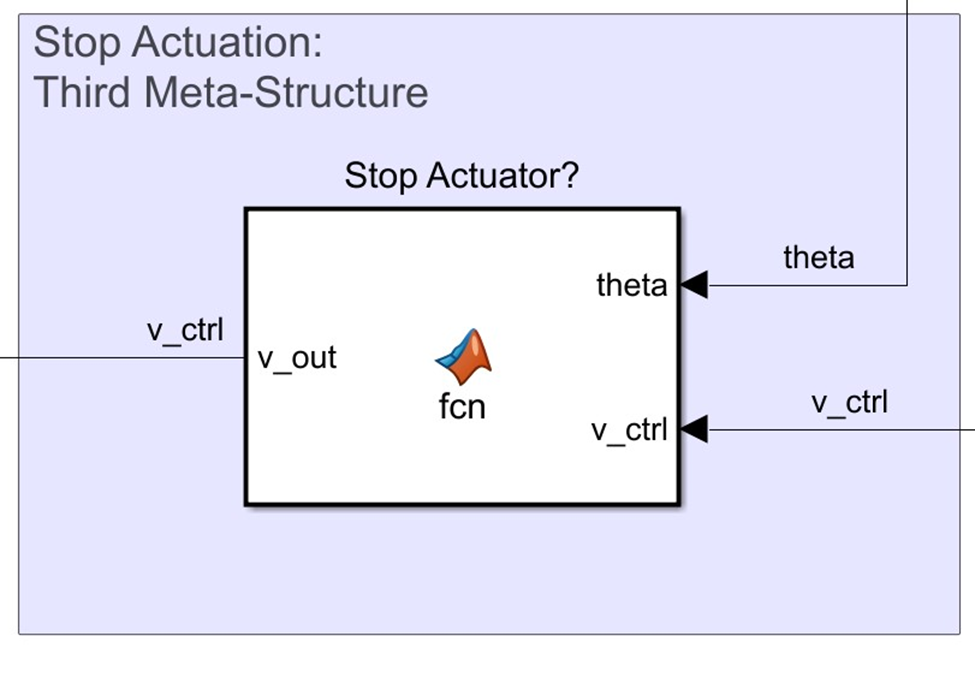

The function for this block is:

#### Switching Control Law

If the $\hat{v}$ condition is satisfied for a particular trajectory, then negative definiteness is determined by how much actuation is left over from the rails. If there is always enough room to combat the uncertainties, then the signum switching law's $\dot{V}$ is negative definite for the trajectory. 


$$\dot{V}(\overset{\rightharpoonup}{x}, s) 

~=~


s(F(\overset{\rightharpoonup}{x})

-

K sign(s)) ~<~ 0  $$



$$
sK sign(s)) 

~>~ 

sF(\overset{\rightharpoonup}{x})






$$
  


$$
K|s|

~>~ 

sF(\overset{\rightharpoonup}{x})






$$
  

where 


$$|v_m| ~=~ |\hat{v} -\frac{K}{b}sign(s)| ~\leq~ 15[V]$$
 

any amount of $v_s$ that exceeds what the actuator can provide will reduce the control law's ability to combat the model uncertainties. With F = 0 however, there is no limitation on $|v_s|$ (so long as $|\hat{v}| < 15V$ condition holds). 

#### Switching Control Law Simulation

Using $\lambda ~=~ 45$ and $\frac{K}{b} ~=~ 10$, a suitable trajectory is found from the initial conditions that keeps $\hat{v}$ within the rails. Initially, the system is simulated with a very large sample frequency of 100KHz. 

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

fric_mod = 1; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer

Three_Ctrl_Struc = 2; %Set to 1 - voltage zeroing control law turned on
                      %Set to 2 - votlage zeroing control law turned off           

Switch_Law = 2;       %Set to 1 - Switching Law with Boundary Layer
                      %Set to 2 - Switching Law without Boundary Layer   
            
%Parameters
K_n = 10*b_n; 
lambda_n= 45; 
C_BL = 0; %Not necessary if the signum switching law with no boundary layer is used

tsim = 5;

t_samp = 1/100000; %Sample time for the sensors (-1) for inherited

NLout = sim('Motorized_Pendulum_VSC');



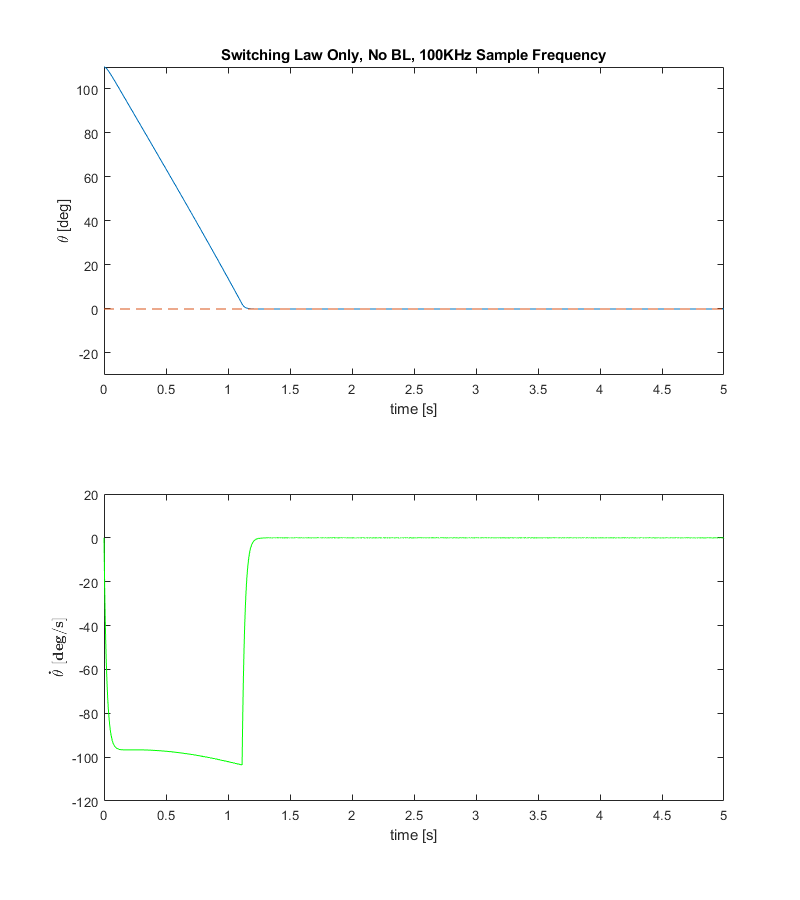

%Plot the results
figure
ax1 = subplot(2,1,1);
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law Only, No BL, 100KHz Sample Frequency')
ylim([-30 max(rad2deg(NLout.x(:,1)))])
% xlim([0 5])


ax2 = subplot(2,1,2);
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
% xlim([0 5])


linkaxes([ax1,ax2],'x');
% xlim([0 5])
set(gcf,'position',[0,0,800,900]);

The performance in this simulation is excellent. This is due to the ability of the actuator to react very quickly to deviations from the switching surface. 

Th_SS_Error = rad2deg(NLout.x(end,1));
Thd_SS_Error = rad2deg(NLout.x(end,2)); 
fprintf(['Steady state angular error was ' num2str(round(Th_SS_Error,3))...
 ' [deg] and steady state angular velocity error was ' num2str(round(Th_SS_Error,3)) ' [deg]'])

Steady state angular error was 0 [deg] and steady state angular velocity error was 0 [deg]

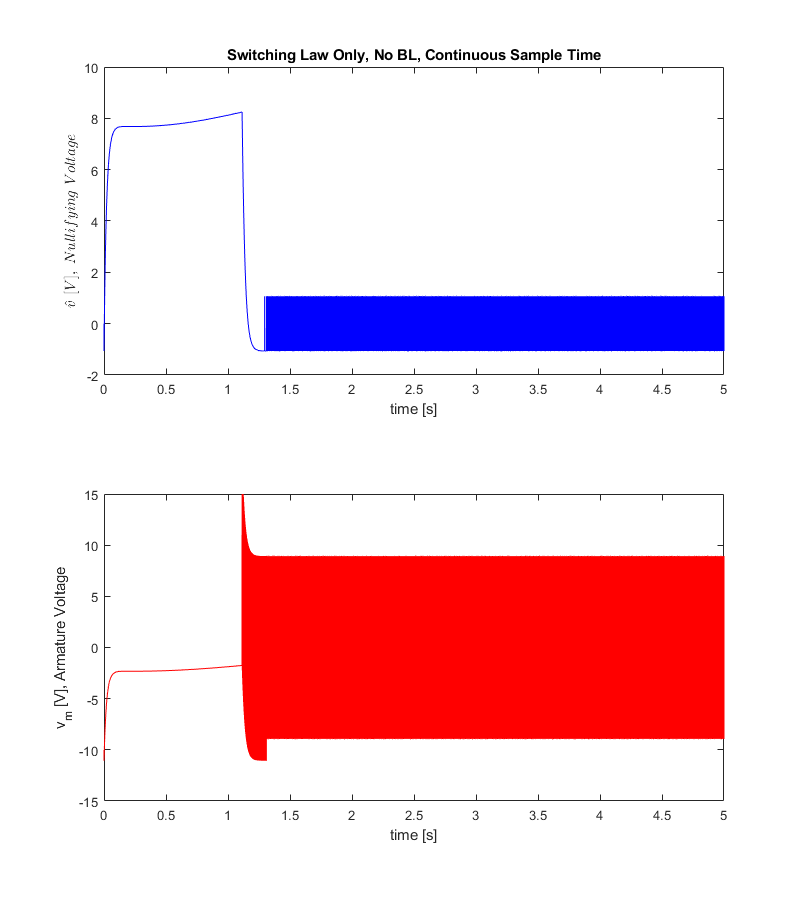


figure
ax1 = subplot(2,1,1);
plot(NLout.tout,NLout.v_hat, 'bl')
xlabel('time [s]')
yl_1 = ylabel('$ \hat{v}~ [V], ~Nullifying ~Voltage $');
set(yl_1, 'Interpreter', 'latex');
title('Switching Law Only, No BL, Continuous Sample Time')
% xlim([0 5])

ax2 = subplot(2,1,2);
plot(NLout.tout,NLout.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V], Armature Voltage')
% xlim([0 5])

linkaxes([ax1,ax2],'x');
% xlim([0 5])
set(gcf,'position',[0,0,800,900]);

The nullifying voltage is shown to be within $\pm 15V$, so that design criterion is satisfied. However, a consequence of the excellent performance is that the actuation chatters rapidly. This is to be expected with a switching law, but it motivates the addition of a boundary layer. The use of a 100KHz sample rate is not realistic - the hardware implimentation has as much slower sample rate of 100Hz. Below, this will be simulated using the switching law that produced these initial results. 

%Set initial conditions to zero velocity and theta of 110 degrees
x0 = [deg2rad(110), 0]';

fric_mod = 1; %Select 1 - couloumb friction with damping and no boundary layer
              %Select 2 - coulomb friction with damping and a smoothing boundary layer

Three_Ctrl_Struc = 2; %Set to 1 - voltage zeroing control law turned on
                      %Set to 2 - votlage zeroing control law turned off           

Switch_Law = 2;       %Set to 1 - Switching Law with Boundary Layer
                      %Set to 2 - Switching Law without Boundary Layer   
            
%Parameters
K_n = 10*b_n; 
lambda_n= 45; 
C_BL = 0.5; %Not necessary if the signum switching law with no boundary layer is used

tsim = 5;

t_samp = 1/100; %Sample time for the sensors (-1) for inherited

NLout = sim('Motorized_Pendulum_VSC');



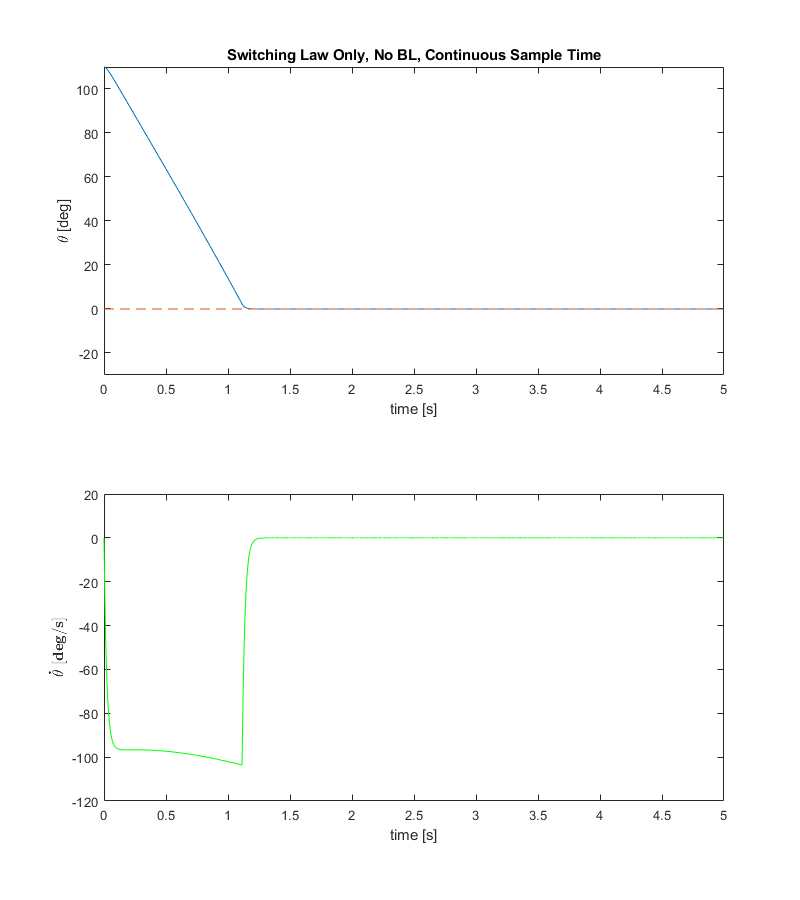

%Plot the results
figure
ax1 = subplot(2,1,1);
plot(NLout.tout,rad2deg(NLout.x(:,1)), [0 NLout.tout(end)], [0 0], '--' )
xlabel('time [s]')
ylabel('\theta [deg]')
title('Switching Law Only, No BL, Continuous Sample Time')
ylim([-30 max(rad2deg(NLout.x(:,1)))])
% xlim([0 5])


ax2 = subplot(2,1,2);
plot(NLout.tout,rad2deg(NLout.x(:,2)), 'g')
xlabel('time [s]')
yl_1 = ylabel('$\bf\dot{\theta}~ [deg/s]$');
set(yl_1, 'Interpreter', 'latex');
% xlim([0 5])


linkaxes([ax1,ax2],'x');
% xlim([0 5])
set(gcf,'position',[0,0,800,900]);

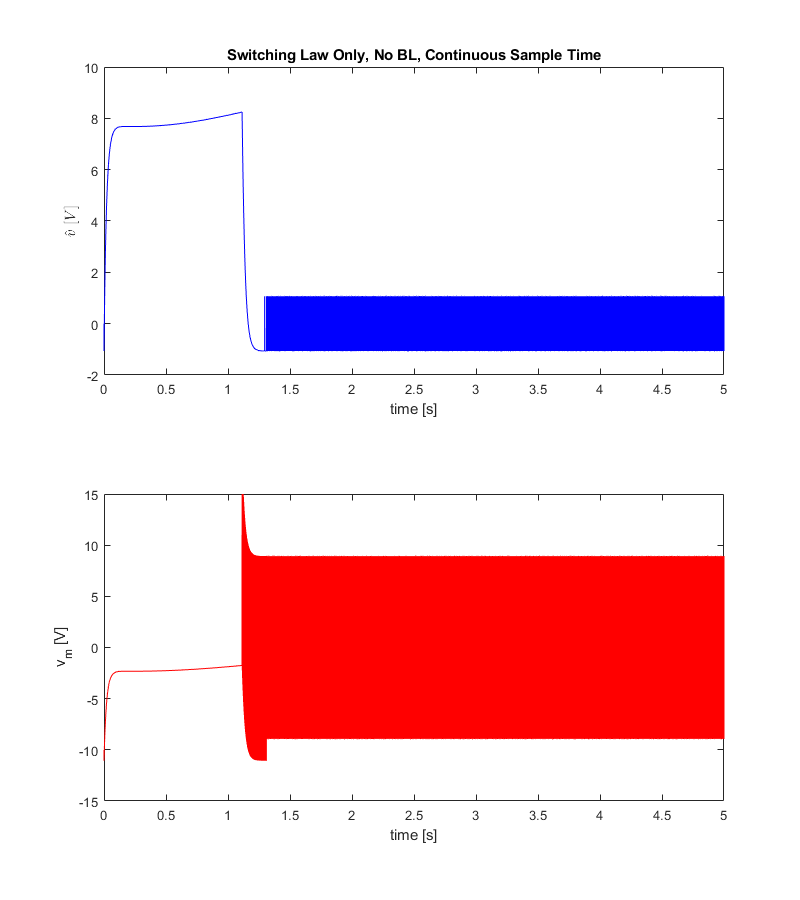


figure
ax1 = subplot(2,1,1);
plot(NLout.tout,NLout.v_hat, 'bl')
xlabel('time [s]')
yl_1 = ylabel('$ \hat{v}~ [V] $');
set(yl_1, 'Interpreter', 'latex');
title('Switching Law Only, No BL, Continuous Sample Time')
% xlim([0 5])

ax2 = subplot(2,1,2);
plot(NLout.tout,NLout.vm, 'r')
xlabel('time [s]')
ylabel('v_m [V]')
% xlim([0 5])

linkaxes([ax1,ax2],'x');
% xlim([0 5])
set(gcf,'position',[0,0,800,900]);

#### Smoothing Boundary Layer

#### Complete Controller Implemenation

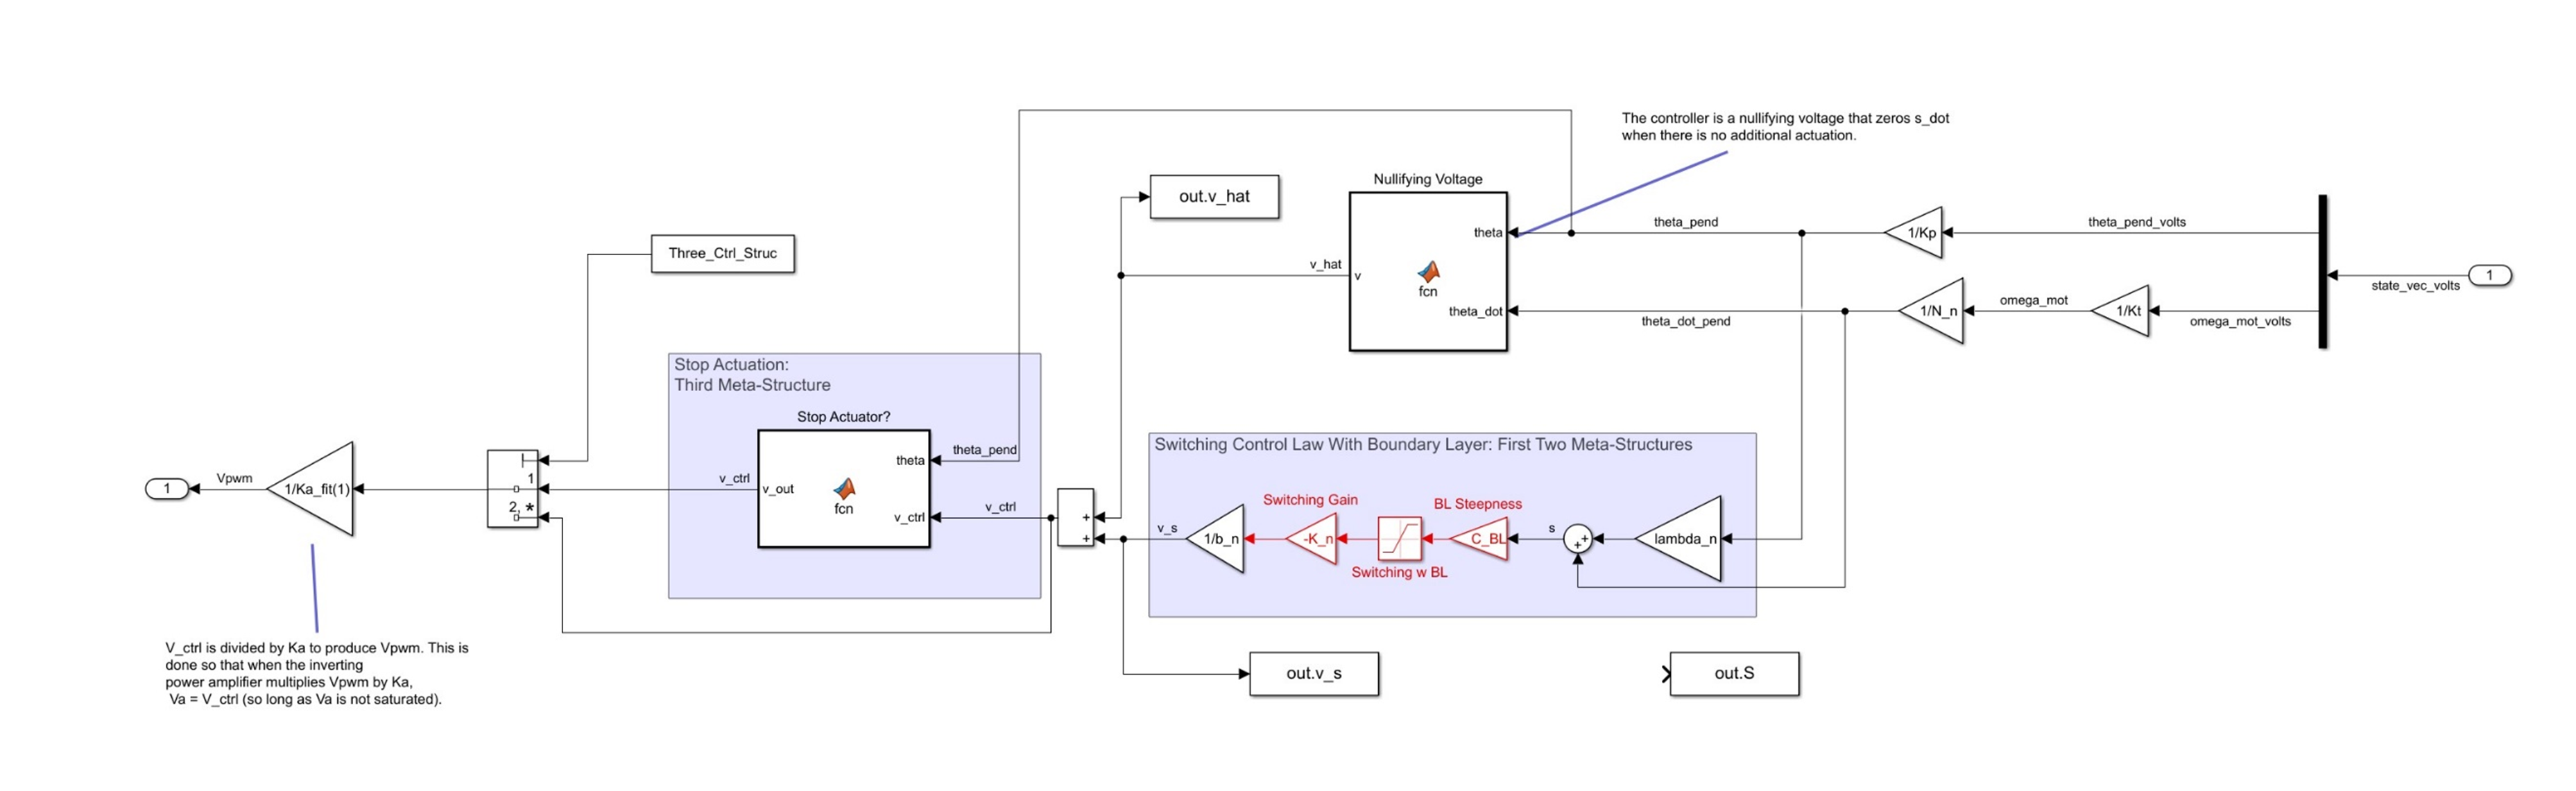

- **Continuous Sample Time SIMULATION**

- **Deterioration With Discrete Sample Time (Motivates Boundary Law) SIMULATION**